So now, the goal comes down to isolating the Kp (proportial for the PID) and using MATLAB's `rlocus()` function on it. So we need to mathematically isolate Kp before we do so. 


$$1+(K_p+K_ds)(\frac{b}{s^2-a})=0
$$



$$s^2-a+bK_p+bK_ds=0
$$



$$s^2+bK_ds-a=-bK_p
$$



$$1+K_p(\frac{b}{s^2+bK_ds-a})=0
$$


So now we have our new transfer function H(s), which we can plot.

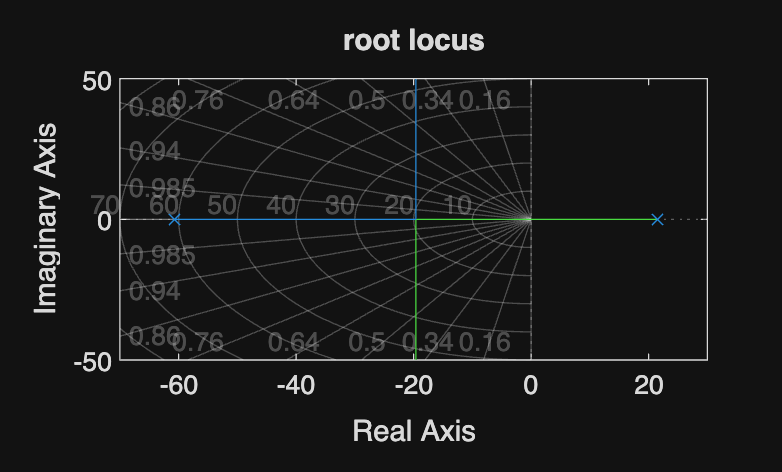

Kd_fixed = 1;
num_rl = b_num;
den_rl = [1, (b_num * Kd_fixed), -a_num];
H_sys = tf(num_rl, den_rl);

figure;
rlocus(H_sys);
title('root locus');
grid on;